clear
clc
clc

Se va a importar la base de datos

% Se escoje la base de datos que se quiere analizar 
% data = importdata("sec1.mat");
data = importdata("sec8.mat"); 
% data = importdata("sec9.mat");

Numero de puntos por anillo

puntos = 20;       

Construcción de los puntos de control 

Matriz_puntos_control = PuntosControl(data, puntos);
% Dimenciones de la matriz de puntos de control 
s = size(Matriz_puntos_control)

s =     61     3     7


Construcción de los parches de Bezier

% Constantes
numero_puntos_u = 4;
numero_puntos_v = 7; 

grado_u = numero_puntos_u - 1; 
grado_v = numero_puntos_v - 1; 

% Desde donde se va a iniciar a ver los parches 
ni = 0;

% Hasta donde se van a ver los parches 
% nf = (puntos - 1);
nf = 0;

Ciclo for que recorre los puntod de control generados anteriormente

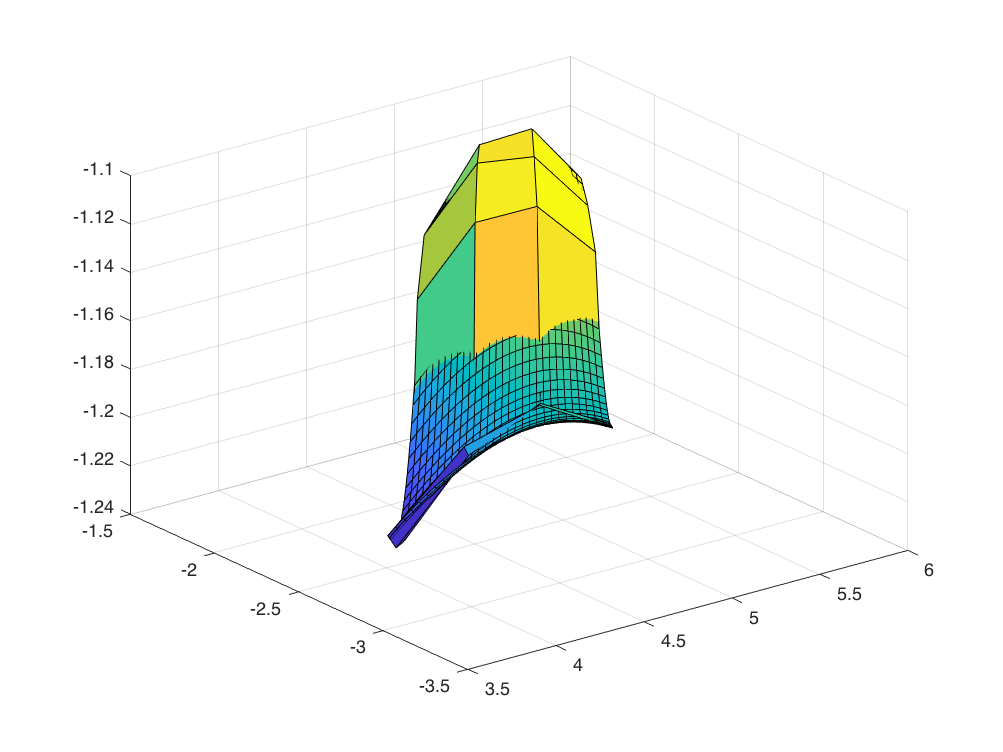

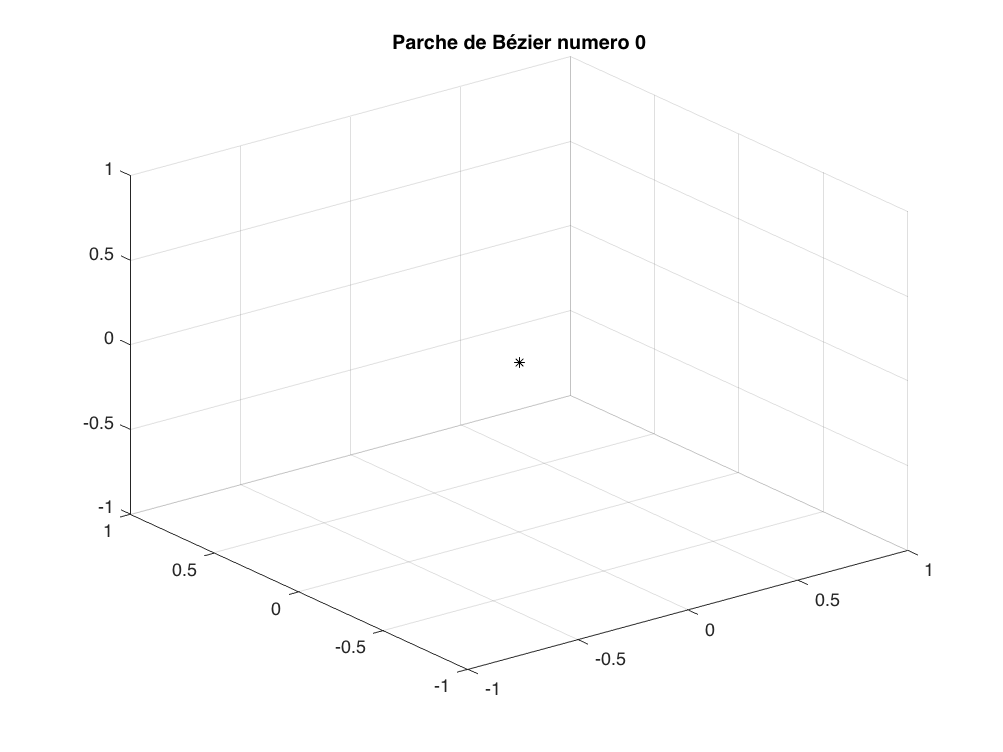

for j = ni:nf

    for i = 1:numero_puntos_v
        Matriz_x(i,:,1) = Matriz_puntos_control((1+(3*j)):(4+(3*j)),1,i);
        Matriz_y(i,:,1) = Matriz_puntos_control((1+(3*j)):(4+(3*j)),2,i);
        Matriz_z(i,:,1) = Matriz_puntos_control((1+(3*j)):(4+(3*j)),3,i);
    end
    
    
% Construcción de los parches de bezier   
    [vector_parche_bezier_x, vector_parche_bezier_y, vector_parche_bezier_z] = ParchesBezier(Matriz_x, Matriz_y, Matriz_z, grado_u, grado_v);
% Despliegue de los parches 
    figure;
    name = 'Parche de Bézier numero ' + string(j);
    title(name);
    surf(Matriz_x,Matriz_y,Matriz_z)
    hold on
    surf(vector_parche_bezier_x,vector_parche_bezier_y,vector_parche_bezier_z)

% Dibujo del origen 
    figure; 
    origen = [0 0 0];
    plot3(origen(1), origen(2),origen(3),'*k','DisplayName','Origen')
    name = 'Parche de Bézier numero ' + string(j) + ' centrado en el origen';
    title(name);
    hold on
    grid on 

end 